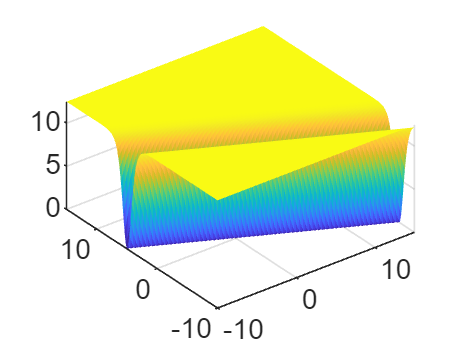

w0 = (-10:0.2:15)';
w1 = (-10:0.2:15)';

[W0,W1] = meshgrid(w0,w1);
x1 = 2;
y  = 0.5;
z  = W0 + x1*W1;
gz = 1./(1+exp(-z));
fL = (y-gz).^2;
surf(W0,W1,50*fL,'EdgeColor', 'none')
axis equal

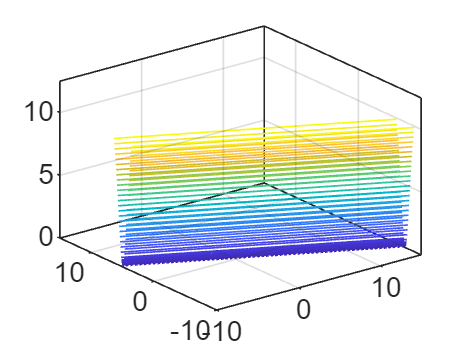


figure

contour3(W0,W1,50*fL,[0:0.1:0.5, 0.7:0.4:10])

Gradient descend starts here

% Initial guess
w = [1; 1];
% Leaning rate
eta = 0.05;
for i=1:400
    z      = w(1) + x1*w(2);
    gz     = 1/(1+exp(-z));
    g_pr_z = gz*(1 - gz);
    dfL_dz = 2*g_pr_z*(gz - y);
    dfL_dw = [dfL_dz;
              dfL_dz*x1];
    w = w - eta*dfL_dw;
end
disp(w)

    0.4000
   -0.1999



fprintf('Gradient equal to %f \n', dfL_dw)

Gradient equal to 0.000017 
Gradient equal to 0.000035 
